clear all;
close all;

## Define Vocal Tract Area Function

beet = [0.8350; 1.2525; 3.3399; 4.1748; 5.0098; 7.2069; 7.5263; 8.0305; 
    8.1061; 8.5660; 7.7656; 8.2341; 4.4964; 2.5395; 1.7213; 1.2525; 1.3202; 1.3202; 
    1.7213; 1.8670; 3.8490; 6.2623; 6.3726; 6.3589];

bought = [0.8350; 1.6699; 4.5923; 2.9521; 2.5395; 3.1795; 3.0105; 2.6732; 
    2.0874; 4.4379; 3.7341; 3.9606; 5.1640; 7.1462; 10.8626; 12.7725; 11.8818; 9.3352; 
    8.4534; 10.6438; 8.9345; 2.4343; 1.8670];

bart = [1.2525; 2.0874; 4.5923; 2.9224; 1.6699; 1.6699; 2.2482; 1.8670; 
    2.0874; 2.9521; 5.0272; 4.1748; 6.3589; 6.2063; 6.3177; 7.5263; 8.8068; 10.3280; 
    10.8546; 10.0976; 8.6066; 6.2623; 8.4017; 5.6784];

boot = [2.0874; 2.9224; 3.7574; 3.7574; 4.6113; 6.0787; 7.8438; 8.1061; 9.1561; 
    7.1095; 7.8771; 6.9106; 5.1640; 2.9521; 3.3399; 3.3659; 3.5670; 2.2482; 2.4343; 
    2.0874; 3.5913; 4.2983; 2.8006; 3.0393];

phoneme = bart;
phoneme_str = '/ɑ:/';

%Setup
dur = 1; % duration of synthesized sample (sec)
c = 350; % speed of sound (m/s)
voice = 2; % 1: male, 2: female, 3:child
fs = 44100; 
tube_width = 0.8; % (cm)

## Generate VT Filter

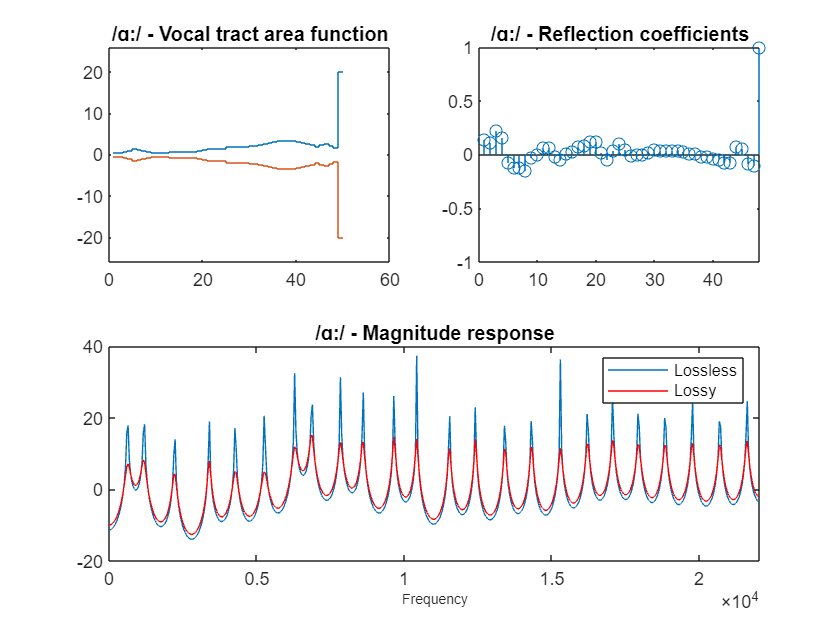

vow = phoneme / pi;

figure 
% Interpolate tube based on vocal tract length and bandwidth
N = round(length(vow) * tube_width / 100 *  fs/2 * 4 / c);
vow = interp1(vow, linspace(1, length(vow), N));
vow = [vow 20 20]; % append "dummy tubes" for display only
subplot(2,2,1);
stairs(vow); ylim([-26 26]); hold on;
stairs(-vow); hold off;
title([phoneme_str ' - Vocal tract area function']);

% Calculate reflection coefficients
refs = []; % calculate reflection coefficients for each boundary
for j=1:length(vow)-3 %omit the last 2 "dummy tubes"
    ref = (vow(j+1)-vow(j)) / (vow(j+1)+vow(j));
    refs = [refs ref];
end

% add the infinite tube
refs = [refs 1]; % add the infinite tube
subplot(2,2,2);
stem(refs); ylim([-1 1]);
title([phoneme_str ' - Reflection coefficients']);

% add a finite (lossy) tube
refslossy = [refs(1:end-1) .71]; 

% Durbin's recursion: from reflection coeffs to filter coefficients
den = [1]; denlossy{1} = [1];
for k=1:length(refs)
    den = [den 0] + [0 fliplr(refs(k)*den)];
    denlossy{1} = [denlossy{1} 0] + [0 fliplr(refslossy(k)*denlossy{1})];
end

num = [zeros(1, round(length(refs)/2)) 1];
subplot(2, 1, 2);
[h,f] = freqz(num, den, 512, fs);
plot(f, 20*log10(abs(h))); xlim([0 fs/2]);
hold on;

[h,f] = freqz(num, denlossy{1}, 512, fs );
plot(f, 20*log10(abs(h)),'r'); xlabel('Frequency','fontsize',7);
title([phoneme_str ' - Magnitude response']);

% Radiation model
% alpha = .8; R = [1 -alpha]; num = conv(R, num);
% [h,f] = freqz(num, denlossy{1}, 512, fs );
% plot(f, 20*log10(abs(h)),'m'); hold off; 
legend('Lossless','Lossy');

## Create a Synthetic Glottal Pulse (Rosenberg)

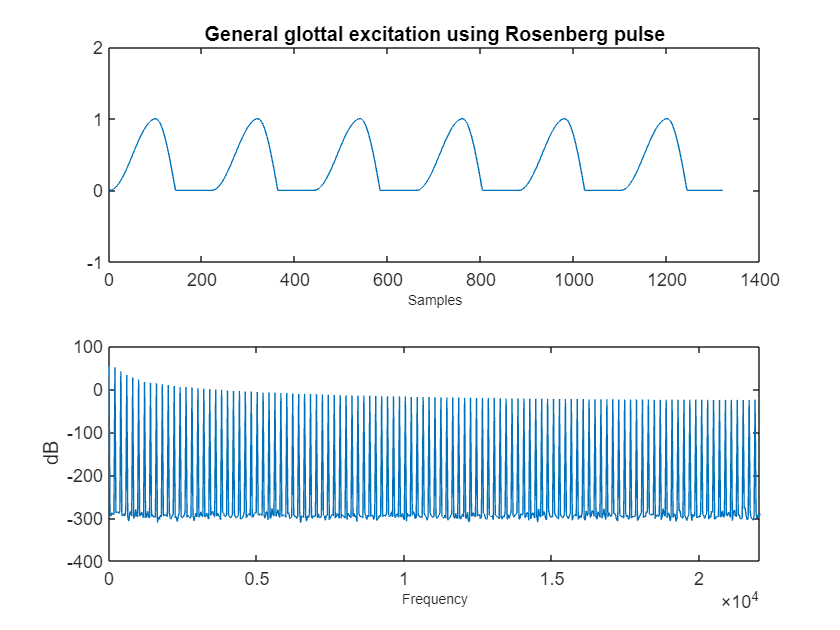

voices = { 'male' 'female' 'child'; 120 200 300; 1 0.8 0.6; .85 .7 .6; .2 .3 .9 }; % label; pitch; vocal tract scale; glottal tense; breathiness
voice = 2;

person = voices{1, voice}; % a label for plots and filenames
pitch = voices{2, voice}; % (hz)
vocal_tract_scale = voices{3, voice};
glottal_tense = voices{4, voice};

% Rosenberg pulse
signal = [];
for i=1:6
	signal = [signal rosenberg(glottal_tense, .65, pitch, fs)];
end

figure; subplot(2,1,1); plot(signal); ylim([-1 2]); xlabel('Samples','fontsize',7);
title('General glottal excitation using Rosenberg pulse');
Y = fft(signal);
Y = abs(Y(1:floor(length(Y)/2))) + eps;
Y = db(Y);
F = linspace(0,fs/2,length(Y))';
subplot(2,1,2);
plot(F,Y); ylabel('dB'); xlabel('Frequency','fontsize',7); xlim([0 fs/2]);

signal = [];

for i=5.5:-1:1
    signal = [signal, .6*rosenberg(.7, .4, pitch, fs), zeros(1, round(2^i+rand*fs/200))];
end

pitchdip = (.98+rand*.02);
pvec = [linspace(pitch, pitch*pitchdip, pitch*dur*14/16) linspace(pitch*pitchdip, pitch/4, pitch*dur*1/10)];
avec = pvec.*pvec/pitch;
gvec = glottal_tense*pvec/pitch;
for i=1:length(pvec)
    roz = avec(i)*rosenberg(gvec(i), .6, pvec(i), fs);
    noisy = conv(rand(1,length(roz)-15), hamming(16));
    roz = (1+noisy*0.03*voices{5,voice}) .* roz;
    signal = [signal roz];
end

env = [linspace(0,1,round(length(signal)/16)) ones(1,round(length(signal)*.75)) linspace(1,0,round(length(signal)/8))];
signal = conv(signal, [.6 1 1 .6]);
[env, signal] = pad(env, signal);
signal = (signal-.5) .* env;

## Excite VT Filter with Rosenberg Glottal Pulse

den = denlossy{1};
output = filter(num, den, signal);
output = output .* 0.7 / max(abs(output)); %normalize

playObj = audioplayer(output,fs) ;
playblocking(playObj) ;

audiowrite('aa_with_rosenberg.wav', output, fs);

## Excite VT Filter with EGG

[egg, fs_egg] = audioread('aa_egg.wav');

egg_smooth = smoothdata(egg, 'movmean', 20) ;
b = 0.5 * [-1, 0, 1] ; % central difference
excitation = filter(b,1,egg_smooth) ;

% derive lpc with egg excitation
output = filter(num, denlossy{1}, excitation);
    
audiowrite('aa_with_egg.wav', output, fs);

Unrecognized function or variable 'plot_formants'.

## Plot Spectrogram

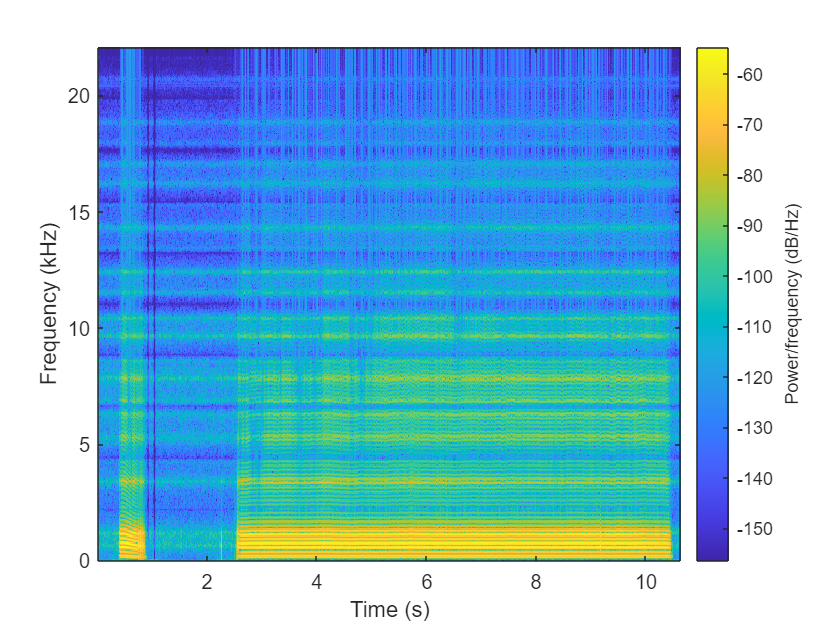

WidebandBandwidth = 50 ;
N_WB = round(fs/WidebandBandwidth);
NarrowbandBandwidth = 10 ;
N_NB = round(fs/NarrowbandBandwidth) ;
percent_Overlap = 0.75 ;
overlap_WB = round(percent_Overlap * N_WB);
overlap_NB = round(percent_Overlap * N_NB);
figure;
spectrogram(output, N_WB, overlap_WB, N_WB, fs, 'yaxis');